MECH532 - Homework 6

Jeremy Primus

October 19, 2018

Problem 1

% intialization
stress = [10:10:100];
global strain_rate_1700k
strain_rate_1700k =  [2e-8 4e-8 6e-8 8e-8 2.3e-7 5e-7 9.9e-7 1.8e-6 3.1e-6 4.9e-6];
strain_rate_1810k = [7e-8 1.4e-7 2.1e-7 2.8e-7 8e-7 1.8e-6 3.5e-6 6.3e-6 1.1e-5 1.7e-5];
strain_rate_1940k = [4.2e-7 8.4e-7 1.3e-6 1.7e-6 4.8e-6 1.1e-5 2.1e-5 3.8e-5 6.5e-5 1e-4];
strain_rate = [strain_rate_1700k; strain_rate_1810k; strain_rate_1940k];

a)

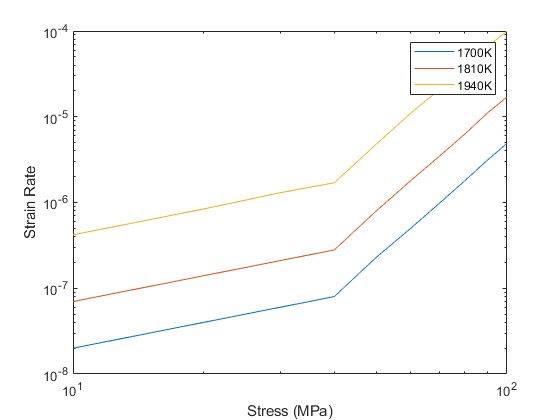

% plot creep rate vs. stress
figure()
for i = 1:3
    %semilogy(stress, strain_rate(i,:))
    loglog(stress, strain_rate(i,:))
    hold on
end
legend('1700K', '1810K', '1940K')
xlabel('Stress (MPa)')
ylabel('Strain Rate')

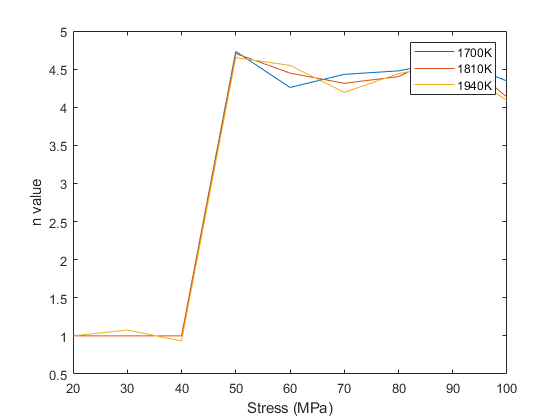

% identify regimes with a plot of log-log slopes
logstrain_rate = log10(strain_rate);
logstress = log10(stress);

% evaluate and plot the derivative in loglog space as this should give the
% n value which will allow visualization of creep mechanism regimes
dydx_1700k = diff(logstrain_rate(1,:)')./diff(logstress(:));                 
dydx_1810k = diff(logstrain_rate(2,:)')./diff(logstress(:));
dydx_1940k = diff(logstrain_rate(3,:)')./diff(logstress(:));
figure()
plot(stress(2:10), dydx_1700k)
hold on
plot(stress(2:10), dydx_1810k)
plot(stress(2:10), dydx_1940k)
legend('1700K', '1810K', '1940K')
xlabel('Stress (MPa)')
ylabel('n value')

The diffusional creep regime is characterized by n=1.  This occurs up to stresses of 40 MPa, at which point power-law creep becomes the dominant mechanism.

b)

For any creep mechanism, the natural log of the strain rate should scale with 1/kT by scale factor Q.

The distinction between Coble and Nabarro-Herring creep can be made through their temperature dependence, which is an exponential relation encapsulated in the diffusion constant.

By plotting temperature vs strain rate (in logspace) for the two different stress regimes, we can quickly identify whether the temperature dependence is the same between the diffusional creep mechanism and the power law creep (PLC) mechanism.

If the temperature dependance is the same, this indicates that the observed diffusional creep operates through the Nabarro-Herring mechanism, as the PLC equation uses the same Q (energy barrier to disrupt lattice).  Their slope (Q/KT) should then be the same.

If diffusional creep procedes by coble creep, the determined slope should be less for diffusional creep than for PLC.

k = 1.38e-23;   % boltzmann constant
figure()
for i = 1:length(strain_rate)
    plot(1./(k*[1700 1810 1940]), log(strain_rate(:,i)))
    hold on
    slope(i) = log(strain_rate(end,i))-log(strain_rate(1,i))/((1/(k*1940)) - (1/(k*1700)));
    disp([num2str(i), num2str(slope(i))])
end

1-14.683


2-13.9899


3-13.5531


4-13.2849


5-12.2469


6-11.4176


7-10.771


8-10.1779


9-9.6411


10-9.2103


diff_Q = exp(mean(slope(1:4)))

diff_Q = 9.3968e-07

std(exp(slope(1:4)))

ans = 5.5531e-07

PLC_Q = exp(mean(slope(5:10)))

PLC_Q = 2.5483e-05

std(exp(slope(5:10)))

ans = 3.6524e-05

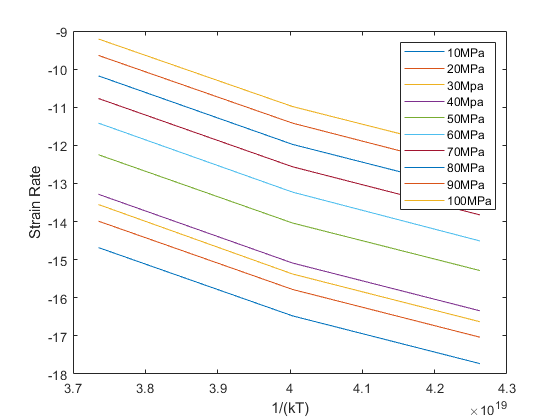


xlabel('1/(kT)')
ylabel('Strain Rate')
legend('10MPa', '20MPa', '30Mpa', '40Mpa', '50MPa', '60MPa', '70MPa', '80MPa', '90MPa', '100MPa')

The Q value determined from the two regimes differs significantly, this rough calculation supports that the diffusional mechanism can be attributed to Coble creep.  The estimated Q value of the diffusional process is lower than that estimated for power law creep, as expected if the diffusional process were governed by a coble mechanism.  The numbers obtained are also roughly in order with those given in the table for problem 2.

c)

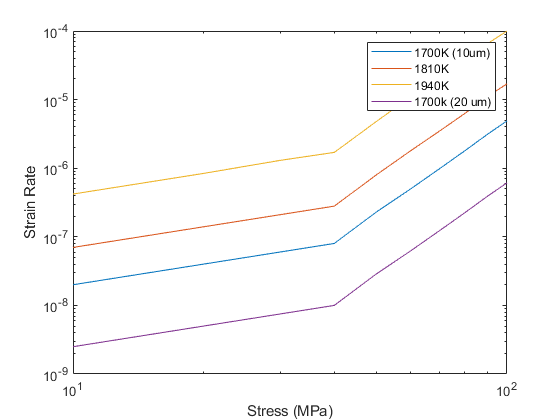

strain_rate_1700k_2d = strain_rate_1700k*(1/2)^3;
% re-plot creep rate vs. stress (couldn't figure out how to plot over a saved figure)
figure()
for i = 1:3
    %semilogy(stress, strain_rate(i,:))
    loglog(stress, strain_rate(i,:))
    hold on
end
hold on
loglog(stress, strain_rate_1700k_2d)
xlabel('Stress (MPa)')
ylabel('Strain Rate')
legend('1700K (10um)', '1810K', '1940K', '1700k (20 um)')

Problem 2

% initialization
global omega d G b k 
% given in problem statement
omega = 1.2e-29;                % atomic volume (m^3/atom)               
DoL = 3.5e-6;                   % lattice diffusion constant - also used in PLC according to 10/3 lecture (m^2/s)
QL = 2e-19;                     % not described, assume this comprises the value Qm+Qf given on pg 102 (J/atom)               
d = 1e-5;                       % grain size (m)
DoC = 1e-5;                     % coble creep diffusion coefficient (m^2/s)
Qc = 1.2e-19;                   % not described, assume this comprises the value Qm+Qf given in eq 5.41 (J/atom)
Apl = 2.5e9;                    % A for PLC 
mpl = 4.8;                      % stress exponent for PLC
G = 25e9;                       % shear modulus for aluminm (Pa)
b = 0.286e-9;                   % burger's vector (m)

% additional constants 
k = 1.38e-23;   % boltzmann constant
Anh = 7;        % A for Nabarro-Herring from Table 5.1
Ac = 50;        % A for coble creep from Table 5.1
n_nh = 2;       % n for NH from Table 5.1
n_c = 3;        % n for coble from Table 5.1 

a)

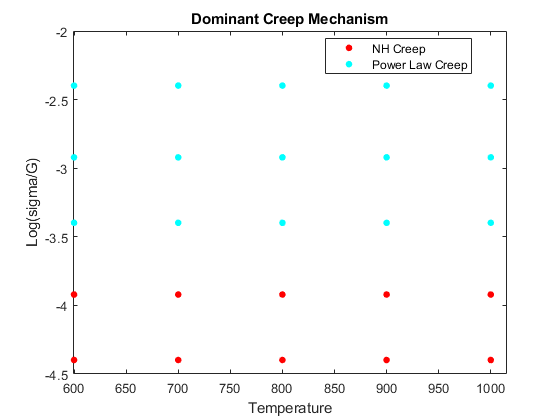

% regimes of interest
temp = [600:100:1000];              % temp (K)
stress = 1e6*[1 3 10 30 100];       % stress (MPa)

% loop through all possible combinations, finding the fastest creep rate at each
figure()
for i = 1:length(temp)
    T =  temp(i);
    for j = 1:length(stress)
        sigma = stress(j);
        % pl creep
        strain_rate_pl(i,j) = uni_creep_eq(Apl, DoL, QL, sigma, mpl, T, 0);
        % coble creep
        strain_rate_c(i,j) = uni_creep_eq(Ac, DoC, Qc, sigma, 0, T, n_c);
        % NH creep
        strain_rate_nh(i,j) = uni_creep_eq(Anh, DoL, QL, sigma, 0, T, n_nh);
        % total strain_rate
        strain_rate = [strain_rate_pl(i,j) strain_rate_c(i,j) strain_rate_nh(i,j)];
        [max_strain_rate(i,j), mechanism(i,j)] = max(strain_rate);

        
    end
    group(mechanism(i,:) == 1) = {'Power Law Creep'};
    group(mechanism(i,:) == 2) = {'Coble Creep'};
    group(mechanism(i,:) == 3) = {'NH Creep'};
    gscatter(T*ones(length(stress),1), log10(stress./G), {group})
    hold on
end
xlabel('Temperature')
ylabel('Log(sigma/G)')
title('Dominant Creep Mechanism')

b)

T = 475+273;                        % temp (K)
strain_rate = 0.01/(1000*3600);     % desired strain rate
% solve for the sigma at this desired strain rate - which mechanism? 
% assumption most creep is due to steady-state creep, ignore stage 1 and stage 3 creep
% looking at the max strain rates determined in part a, all calculated
% strain rates are far higher than the desired strain rate. To acheive the
% desired strain rate, the stress must be much lower than any of the values
% used in calculating this chart.  Therefore, we can rule out PLC. NH seems to dominate 
% at low stress levels.  Calculating the stress to give the desired creep rate, assuming NH
% yields a stress.  We can calculate strain rates at that stress to confirm
% that indeed NH gives the maximum strain rate at this stress.  And to be
% certain, calculating the stress to give the desired creep rate, assuming
% Coble yields a stress.  At this calculated stress, however, NH mechanism
% still dominates.  Therefore we should use the stress from the NH
% calculation.  

sigma_t_c = strain_rate/(Ac*DoC*exp(Qc/(k*T)))*omega^(2/3)*k*T/omega*(d/b)^n_c;
sigma_t_nh = strain_rate/(Anh*DoL*exp(QL/(k*T)))*omega^(2/3)*k*T/omega*(d/b)^n_nh;

% coble creep
strain_rate_c = uni_creep_eq(Ac, DoC, Qc, sigma_t_nh, 0, T, n_c);
% NH creep
strain_rate_nh = uni_creep_eq(Anh, DoL, QL, sigma_t_nh, 0, T, n_nh);

strain_rate = [strain_rate_c strain_rate_nh];
[max_strain_rate, mechanism] = max(strain_rate);
if mechanism == 1
    disp(['Coble creep. Sigma = ', num2str(sigma_t_c)])
end
if mechanism == 2
    disp(['NH creep. Sigma = ', num2str(sigma_t_nh)])
end

NH creep. Sigma = 2.4057e-14


% check the sigma_t value calculated from coble creep equation to confirm that NH is still dominant mechanism here
% coble creep
strain_rate_c = uni_creep_eq(Ac, DoC, Qc, sigma_t_c, 0, T, n_c);
% NH creep
strain_rate_nh = uni_creep_eq(Anh, DoL, QL, sigma_t_c, 0, T, n_nh);

strain_rate = [strain_rate_c strain_rate_nh];
[max_strain_rate, mechanism] = max(strain_rate);
if mechanism == 1
    disp(['Coble creep. Sigma = ', num2str(sigma_t_c)])
end
if mechanism == 2
    disp(['NH creep. Sigma = ', num2str(sigma_t_nh)])
end

NH creep. Sigma = 2.4057e-14


The output here confirms that NH creep is the dominant mechanism and should be used in the universal creep equation to determine the maximum stress to meet the material requirements.  (See bottom of script for uni_creep_eq function definition.)

c) To engineer an aluminum alloy to creep at the desired rate and maximize the applied stress, one should attempt to modulate the diffusivity and grain size of the material.  Decreasing grain size will have a moderate effect on decreasing the creep rate aned can be done via processing methods, while decreasing diffusivity can have a pronounced effect on creep rates.  This can be accomplished by a number of methods (decreasing lattice spacing, increasing bond strength or atomic size, etc.) perhaps the most straightforward method would be to close down the crystal structure.  Aluminum is an FCC lattice.  Loading interstitial sites with a solute will close down the structure further making the activation barrier to diffusion higher.  This is just one method which could be used to optimize loading at a desired creep rate.  

Problem 3

    The Griffith criterion for fracture is:


$$\sigma_F =\sqrt{\frac{2E\gamma_S }{\pi a}}$$


global sigma_F E a
sigma_F = [57.3 33.5 21.5 17.8 16.7 15.6]*1e6;  % fracture strength (Pa)
a = [101 305 697 912 1220 1390]*1e-6;           % crack length (m)
E = 380e9;                                      % Young's modulus (Pa)

We can use linear regression to determine the most likely value of $\gamma_S$

gamma_s = fminsearch(@lsfit, 1)

gamma_s = 1.3671

Dimensional analysis yields units of Joules/m^2


$$\gamma_S =1\ldotp 37\;\frac{J}{m^2 }$$


function strain_rate = uni_creep_eq(A,D,Q,sigma,m,T,n)
% function to calculate strain rates from the universal creep equation
    global omega d G b k 
    D_t = D*exp(Q/(k*T));
    strain_rate = A*D_t/(omega^(2/3))*((sigma/G)^m)*((sigma*omega)/(k*T))*(b/d)^n;
end

function s = lsfit(so)
% function to conduct least squares fit to determine surface energy 
global sigma_F E a
    s = sum((sigma_F - sqrt(so*2*E./(pi.*a))).^2);
end